문제 1

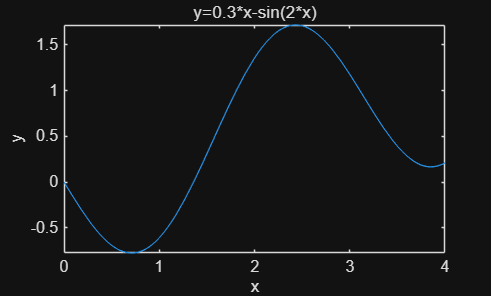

fplot(@bms_25012520_func_1,[0,4])

xlabel('x');%x축이름 표시
ylabel('y')%y축 이름 표시
title('y=0.3*x-sin(2*x)')%이름 표시


root1=fzero(@bms_25012520_func_1,[0,1])

root1 = 0

root2=fzero(@bms_25012520_func_1,[1,2])

root2 = 1.3606

q1_b=fminbnd(@bms_25012520_func_1,0,4)

q1_b = 0.7101

q1=bms_25012520_func_1(q1_b)

q1 = -0.7757

그래프를 통해 함수의 형태를 확인한 후

fminbnd(@bms_25012520_func_1,[0,4])를 이용하여

구간 [0,4]에서 최소가 되는 x값이 약 0.7101임을 구하였다.

따라서 이 점에서 [0,4] 구간 내 최소값을 갖는다고 판단할 수 있다.

문제2

[t1,t2]= bms_25012520_func_2(100,50,9.81)

t1 = 2.7324

t2 = 7.4612

이 함수의 답을 보면 이 물체를 던졌을때 100m에 두번 도달하는 걸 알 수 있다. t1은 물체가 상승하면서 첫번쨰로 100m에 도달하는 시간이고 t2는 최고점을 찍고 그 후에 하강하면서 100m에 도달하는 점이라는 것을 의미한다.

문제 3

(a) V=(pi*r^2*h)/3이다

그러므로 이를 h에 대해 정리하면

h=(3*V)/(pi*r^2)이다

그러므로 이를 두번째 식에 대입하면

A=pi*r*sqrt(r^2+((3*V)/(pi*r^2))^2)처럼 h를 소거하여 A에 대한 식을 r과 V의 함수로 구할수 있다.

global V;
V=10;
r_min=fminbnd(@bms_25012520_func_3b,1,10) %A를 최소화 하는 r값 구함

r_min = 1.8901

h=(3*V)/(pi*r_min^2) %그때 상응하는 높이 h값을 구함

h = 2.6730

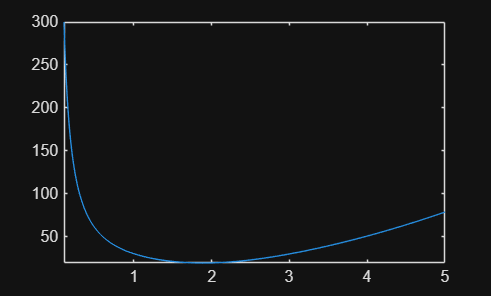


fplot(@bms_25012520_func_3b,[0.1,5]) 

A_min=bms_25012520_func_3b(r_min)%최소값을 찾음

A_min = 19.4393

A_max=A_min*1.1

A_max = 21.3833

f=@(r)bms_25012520_func_3b(r)-A_max;
r1=fzero(f,r_min-1)%함수 근처에서 1.1배가 되는 r값을 찾는다

r1 = 1.4823

r2=fzero(f,r_min+1)

r2 = 2.3316

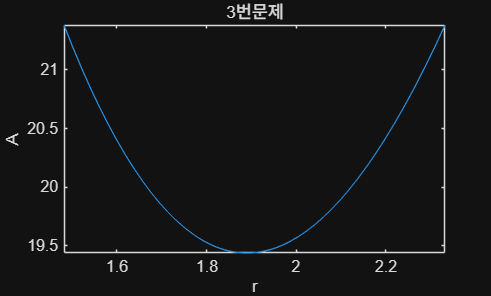


fplot(@bms_25012520_func_3b,[1.4823,2.3316])%민감도 조사를 위해서 그래프 그림

xlabel('r');%x축이름 표시
ylabel('A')%y축 이름 표시
title('3번문제')%이름 표시


left=r_min-r1

left = 0.4078

right=r2-r_min %얼마나 벗어날수 있는지 계산

right = 0.4415

%오른쪽 값이 더 크므로 최적값에서 0.4415만큼 더 벗어날 수 있다.

문제4

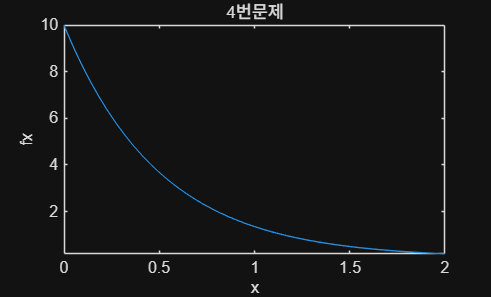

fx=@(x) 10.*exp(-2.*x);%익명 함수 생성
fplot(fx,[0,2])%그래프 그림

xlabel('x');%x축이름 표시
ylabel('fx')%y축 이름 표시
title('4번문제')%이름 표시

문제 5

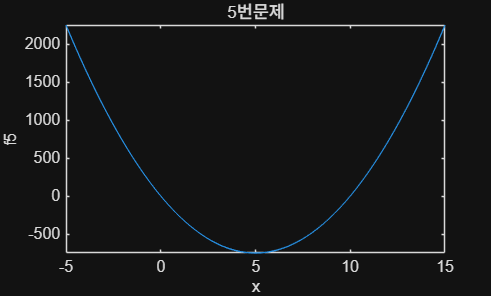

f5=@(x) 30.*(x.^2)-300.*x+4; %익명 함수 생성
fplot(f5,[-5,15])%함수의 그래프를 그림

xlabel('x');%x축이름 표시
ylabel('f5')%y축 이름 표시
title('5번문제')%이름 표시


f5_min=fminbnd(f5,0,10)%x가 5일떄

f5_min = 5.0000

f5_mi=f5(5)%-746의 최소값을 가짐

f5_mi = -746

문제 6

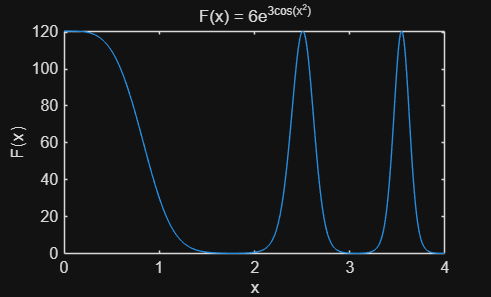

h=@(z) 6.*exp(z);
g=@(y) 3.*cos(y); 
f=@(x) x.^2;%익명 함수 생성

F=@(x) h(g(f(x)));

fplot(F,[0,4])%그래프를 그림
xlabel('x');%x축이름 표시
ylabel('F(x)')%y축 이름 표시
title('F(x) = 6e^{3cos(x^2)}')%이름 표시